[I, map] = imread('C:\dev\biomedeng\Associated Files\Chapter 14\bacteria.tif')

I = 178×178 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   117   116   116   115   115   116   117   117   117   116   115   115   115   115   115   115   114   113   112   112   112   111   110   110   109   108   108   109   109   110   110   111   111   111   111   111   111   111   112   114   117   118   119   119   120   121   121   120   121
     0   116   116   115   115   115   116   116   116   116   115   114   114   115   115   115   115   114   113   112   112   112   112   112   111   111   110   110   110   110   110   110   111   111   111   111   111   111   111   112   114   118   120   121   123   123   123   122   122   122
     0   115   115   115   115   115   116   115   115   115   114   114


map =

     []



I = im2double(I)

I =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.4588    0.4549    0.4549    0.4510    0.4510    0.4549    0.4588    0.4588    0.4588    0.4549    0.4510    0.4510    0.4510    0.4510    0.4510    0.4510    0.4471    0.4431    0.4392    0.4392    0.4392    0.4353    0.4314    0.4314    0.4275    0.4235    0.4235    0.4275    0.4275    0.4314    0.4314    0.4353    0.4353    0.4353    0.4353    0.4353    0.4353    0.4353    0.4392    0.4471    0.4588    0.4627    0.4667    0.4667    0.4706    0.4745    0.4745    0.4706    0

I = im2gray(I)

I =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.4588    0.4549    0.4549    0.4510    0.4510    0.4549    0.4588    0.4588    0.4588    0.4549    0.4510    0.4510    0.4510    0.4510    0.4510    0.4510    0.4471    0.4431    0.4392    0.4392    0.4392    0.4353    0.4314    0.4314    0.4275    0.4235    0.4235    0.4275    0.4275    0.4314    0.4314    0.4353    0.4353    0.4353    0.4353    0.4353    0.4353    0.4353    0.4392    0.4471    0.4588    0.4627    0.4667    0.4667    0.4706    0.4745    0.4745    0.4706    0

I_e = edge(I,'canny',0.2)% 1. Apply Canny edge filter with 0.2 tresh

I_e = 178×178 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


%Dilate 
structure = strel("disk", 1);
I_dilated = imdilate(I_e, structure); 

bw1 = imbinarize(I)

bw1 = 178×178 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

I_comb = I + I_dilated % 2. Add edges to grayscale

I_comb =          0    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.4588    1.4549    1.4549    1.4510    1.4510    0.4549    0.4588    0.4588    0.4588    0.4549    0.4510    0.4510    0.4510    0.4510    0.4510    0.4510    1.4471    1.4431    1.4392    1.4392    1.4392    1.4353    1.4314    1.4314    1.4275    1.4235    1.4235    1.4275    1.4275    0.4314    0.4314    0.4353    0.4353    1.4353    1.4353    1.4353    1.4353    1.4353    1.4392    1.4471    1.4588    1.4627    1.4667    1.4667    1.4706    1.4745    1.4745    1.4706


I_fill = imfill(I_comb, 'holes')%3. Apply imfill to this combined image that will make

I_fill =          0    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.4588    1.4549    1.4549    1.4510    1.4510    0.4549    0.4588    0.4588    0.4588    0.4549    0.4510    0.4510    0.4510    0.4510    0.4510    0.4510    1.4471    1.4431    1.4392    1.4392    1.4392    1.4353    1.4314    1.4314    1.4275    1.4235    1.4235    1.4275    1.4275    0.4314    0.4314    0.4353    0.4353    1.4353    1.4353    1.4353    1.4353    1.4353    1.4392    1.4471    1.4588    1.4627    1.4667    1.4667    1.4706    1.4745    1.4745    1.4706

%the interior of all but one cell white.


I_t = im2bw(I_fill, 0.99)%High treshhold to capture bactira mask

I_t = 178×178 logical array
   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

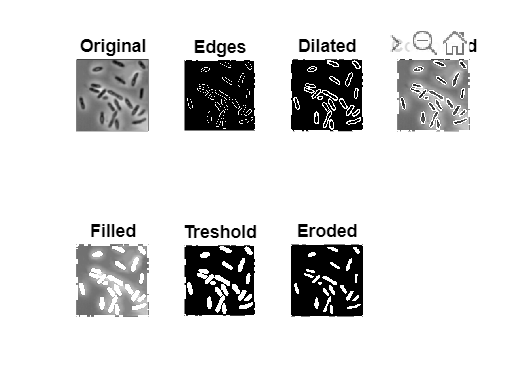


%Capture the last 
structure = strel("disk", 2);
I_eroded = imerode(I_t, structure); 


subplot(2,4,1)
imshow(I)
title('Original')
subplot(2,4,2)
imshow(I_e)
title('Edges')
subplot(2,4,3)
imshow(I_dilated)
title('Dilated')
subplot(2,4,4)
imshow(I_comb)
title('Combined')

subplot(2,4,5)
imshow(I_fill)
title('Filled')

subplot(2,4,6)
imshow(I_t)
title('Treshold')

subplot(2,4,7)
imshow(I_eroded)
title('Eroded')

figure;

